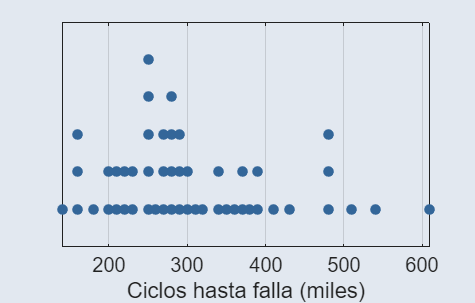

datos = [163, 392, 269, 366, 605, 299, 287, 162, 222, 287, ...
         348, 405, 253, 159, 227, 483, 206, 273, 509, 141, ...
         319, 537, 211, 302, 483, 182, 294, 378, 344, 277, ...
         204, 284, 250, 280, 248, 425, 386, 234, 310, 224, ...
         273, 245, 339, 250, 275, 364, 262, 480, 197, 373];

datos = sort(datos);

% Apilar puntos que caen en el mismo valor (o valores muy cercanos)
[valores_unicos, ~, idx] = unique(round(datos / 10) * 10);  % agrupa en bins de 10
y_stack = zeros(size(datos));
for i = 1:length(valores_unicos)
    pos = find(idx == i);
    y_stack(pos) = 1:length(pos);
end

color_fondo = [226 232 240] / 255;

figure('Color', color_fondo);
set(gcf, 'Units', 'inches', 'Position', [0 0 5.5 3.5]);
scatter(round(datos / 10) * 10, y_stack, 40, [0.2 0.4 0.6], 'filled');
set(gca, 'FontSize', 12, 'Color', 'none', 'YTick', []);
xlabel('Ciclos hasta falla (miles)');
ylim([0, max(y_stack) + 1]);
grid on;
box on;

set(gcf, 'Units', 'inches', 'Position', [0 0 5.5 3.5]);
exportgraphics(gcf, 'puntos_rodamientos.png', 'Resolution', 300);